# Exam February 5, 2018

## Exercise 1

close all

q = sym('q',[1 4])

$$q = \left(\begin{array}{cccc} q_{1} & q_{2} & q_{3} & q_{4} \end{array}\right)$$

dh = [pi/2 0 202 q(1);
        0   210.5 0  q(2);
        0   268  0  q(3);
        pi/2 174.5 0  q(4)]

$$dh = \left(\begin{array}{cccc} \frac{\pi }{2} & 0 & 202 & q_{1}\\ 0 & \frac{421}{2} & 0 & q_{2}\\ 0 & 268 & 0 & q_{3}\\ \frac{\pi }{2} & \frac{349}{2} & 0 & q_{4} \end{array}\right)$$

dht = getDHforTB(dh,'alpha')

n = 4

dht =          0  202.0000         0    1.5708
         0         0  210.5000         0
         0         0  268.0000         0
         0         0  174.5000    1.5708


comau = SerialLink(dht)

 
comau = 
 
noname:: 4 axis, RRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        202|          0|     1.5708|          0|
|  2|         q2|          0|      210.5|          0|          0|
|  3|         q3|          0|        268|          0|          0|
|  4|         q4|          0|      174.5|     1.5708|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


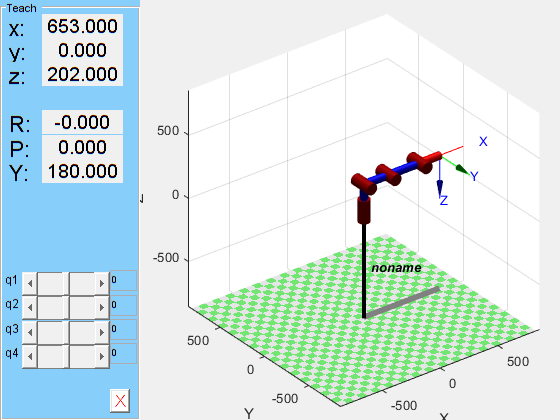


comau.teach([0 0 0 0])

## Exercise 4

Calculate a spline

q = sym('q',[1,4]);
syms t t1 t2 v2 v3 t3 t4

#### Part A

a = sym('a',[1 3]);
tao = (t-t1)/(t2-t1)

$$tao = -\frac{t-t_{1}}{t_{1}-t_{2}}$$

qa = q(1) + a(1)*tao + a(2)*tao^2 + a(3)*tao^3 %tao must be defined as a function of t

$$qa = q_{1}-\frac{a_{1}\,\left(t-t_{1}\right)}{t_{1}-t_{2}}+\frac{a_{2}\,{\left(t-t_{1}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{a_{3}\,{\left(t-t_{1}\right)}^{3}}{{\left(t_{1}-t_{2}\right)}^{3}}$$

wa = diff(qa,t)

$$wa = \frac{a_{2}\,\left(2\,t-2\,t_{1}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{a_{1}}{t_{1}-t_{2}}-\frac{3\,a_{3}\,{\left(t-t_{1}\right)}^{2}}{{\left(t_{1}-t_{2}\right)}^{3}}$$

% Forming the equation system for part A

eqA(1) = subs(qa,t,t2) == q(2);
eqA(2) = simplify(subs(wa,t,t1)) == 0; % t = t1 is tao = 0
eqA(3) = simplify(subs(wa,t,t2)) == v2; % t = t2 is tao = 1
eqA.'

$$ans = \left(\begin{array}{c} a_{1}+a_{2}+a_{3}+q_{1}=q_{2}\\ -\frac{a_{1}}{t_{1}-t_{2}}=0\\ -\frac{a_{1}+2\,a_{2}+3\,a_{3}}{t_{1}-t_{2}}=v_{2} \end{array}\right)$$

[a1 a2 a3] = solve(eqA.',a) 

$$a1 = 0$$

$$a2 = 3\,q_{2}-3\,q_{1}+t_{1}\,v_{2}-t_{2}\,v_{2}$$

$$a3 = 2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2}$$

### Part B

taob = (t-t2)/(t3-t2)

$$taob = -\frac{t-t_{2}}{t_{2}-t_{3}}$$

b = sym('b',[1 3]);

qb = q(2) + b(1)*taob + b(2)*taob^2 + b(3)*taob^3 %tao must be defined as a function of t

$$qb = q_{2}-\frac{b_{1}\,\left(t-t_{2}\right)}{t_{2}-t_{3}}+\frac{b_{2}\,{\left(t-t_{2}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{b_{3}\,{\left(t-t_{2}\right)}^{3}}{{\left(t_{2}-t_{3}\right)}^{3}}$$

wb = diff(qb,t)

$$wb = \frac{b_{2}\,\left(2\,t-2\,t_{2}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{b_{1}}{t_{2}-t_{3}}-\frac{3\,b_{3}\,{\left(t-t_{2}\right)}^{2}}{{\left(t_{2}-t_{3}\right)}^{3}}$$

 
% Forming the equation system for part B

eqB(1) = subs(qb,t,t3) == q(3);
eqB(2) = simplify(subs(wb,t,t2)) == v2; % t = t1 is tao = 0
eqB(3) = simplify(subs(wb,t,t3)) == v3; % t = t2 is tao = 1
eqB.'

$$ans = \left(\begin{array}{c} b_{1}+b_{2}+b_{3}+q_{2}=q_{3}\\ -\frac{b_{1}}{t_{2}-t_{3}}=v_{2}\\ -\frac{b_{1}+2\,b_{2}+3\,b_{3}}{t_{2}-t_{3}}=v_{3} \end{array}\right)$$

[b1 b2 b3] = solve(eqB.',b) 

$$b1 = t_{3}\,v_{2}-t_{2}\,v_{2}$$

$$b2 = 3\,q_{3}-3\,q_{2}+2\,t_{2}\,v_{2}+t_{2}\,v_{3}-2\,t_{3}\,v_{2}-t_{3}\,v_{3}$$

$$b3 = 2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3}$$

### Part C

taoc = (t-t3)/(t4-t3)

$$taoc = -\frac{t-t_{3}}{t_{3}-t_{4}}$$

c = sym('c',[1 3]);

qc = q(3) + c(1)*taoc + c(2)*taoc^2 + c(3)*taoc^3 %tao must be defined as a function of t

$$qc = q_{3}-\frac{c_{1}\,\left(t-t_{3}\right)}{t_{3}-t_{4}}+\frac{c_{2}\,{\left(t-t_{3}\right)}^{2}}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{c_{3}\,{\left(t-t_{3}\right)}^{3}}{{\left(t_{3}-t_{4}\right)}^{3}}$$

wc = diff(qc,t)

$$wc = \frac{c_{2}\,\left(2\,t-2\,t_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{c_{1}}{t_{3}-t_{4}}-\frac{3\,c_{3}\,{\left(t-t_{3}\right)}^{2}}{{\left(t_{3}-t_{4}\right)}^{3}}$$

 
% Forming the equation system for part C

eqC(1) = subs(qc,t,t4) == q(4);
eqC(2) = simplify(subs(wc,t,t3)) == v3; % t = t1 is tao = 0
eqC(3) = simplify(subs(wc,t,t4)) == 0; % t = t2 is tao = 1
eqC.'

$$ans = \left(\begin{array}{c} c_{1}+c_{2}+c_{3}+q_{3}=q_{4}\\ -\frac{c_{1}}{t_{3}-t_{4}}=v_{3}\\ -\frac{c_{1}+2\,c_{2}+3\,c_{3}}{t_{3}-t_{4}}=0 \end{array}\right)$$

[c1, c2, c3] = solve(eqC.',c)

$$c1 = t_{4}\,v_{3}-t_{3}\,v_{3}$$

$$c2 = 3\,q_{4}-3\,q_{3}+2\,t_{3}\,v_{3}-2\,t_{4}\,v_{3}$$

$$c3 = 2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3}$$

%Look for the velocity values
acca= diff(wa,t)

$$acca = \frac{2\,a_{2}}{{\left(t_{1}-t_{2}\right)}^{2}}-\frac{3\,a_{3}\,\left(2\,t-2\,t_{1}\right)}{{\left(t_{1}-t_{2}\right)}^{3}}$$

accb= diff(wb,t)

$$accb = \frac{2\,b_{2}}{{\left(t_{2}-t_{3}\right)}^{2}}-\frac{3\,b_{3}\,\left(2\,t-2\,t_{2}\right)}{{\left(t_{2}-t_{3}\right)}^{3}}$$

accc= diff(wc,t)

$$accc = \frac{2\,c_{2}}{{\left(t_{3}-t_{4}\right)}^{2}}-\frac{3\,c_{3}\,\left(2\,t-2\,t_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{3}}$$


acca_1 =simplify(subs(acca,[t a(2) a(3)],[t2 a2 a3]))

$$acca\_1 = \frac{2\,\left(3\,q_{1}-3\,q_{2}-2\,t_{1}\,v_{2}+2\,t_{2}\,v_{2}\right)}{{\left(t_{1}-t_{2}\right)}^{2}}$$

accb_0 =simplify(subs(accb,[t b(2) b(3)],[t2 b2 b3]))

$$accb\_0 = -\frac{2\,\left(3\,q_{2}-3\,q_{3}-2\,t_{2}\,v_{2}-t_{2}\,v_{3}+2\,t_{3}\,v_{2}+t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

accb_1 =simplify(subs(accb,[t b(2) b(3)],[t3 b2 b3]))

$$accb\_1 = \frac{2\,\left(3\,q_{2}-3\,q_{3}-t_{2}\,v_{2}-2\,t_{2}\,v_{3}+t_{3}\,v_{2}+2\,t_{3}\,v_{3}\right)}{{\left(t_{2}-t_{3}\right)}^{2}}$$

accc_0 =simplify(subs(accc,[t c(2) c(3)],[t3 c2 c3]))

$$accc\_0 = -\frac{2\,\left(3\,q_{3}-3\,q_{4}-2\,t_{3}\,v_{3}+2\,t_{4}\,v_{3}\right)}{{\left(t_{3}-t_{4}\right)}^{2}}$$


[v2sol, v3sol] = solve([acca_1 == accb_0;
                       accb_1 == accc_0],[v2 v3])

$$v2sol = \frac{3\,\left(q_{3}\,{t_{2}}^{4}-q_{4}\,{t_{2}}^{4}-2\,q_{1}\,t_{2}\,{t_{3}}^{3}-2\,q_{1}\,{t_{2}}^{3}\,t_{3}-2\,q_{3}\,t_{1}\,{t_{2}}^{3}+2\,q_{1}\,{t_{2}}^{3}\,t_{4}+2\,q_{2}\,t_{2}\,{t_{3}}^{3}+2\,q_{4}\,t_{1}\,{t_{2}}^{3}+2\,q_{1}\,{t_{3}}^{3}\,t_{4}-2\,q_{2}\,{t_{3}}^{3}\,t_{4}-2\,q_{3}\,{t_{2}}^{3}\,t_{4}+2\,q_{4}\,{t_{2}}^{3}\,t_{3}+4\,q_{1}\,{t_{2}}^{2}\,{t_{3}}^{2}+q_{2}\,{t_{1}}^{2}\,{t_{3}}^{2}+q_{3}\,{t_{1}}^{2}\,{t_{2}}^{2}-2\,q_{1}\,{t_{2}}^{2}\,{t_{4}}^{2}-q_{2}\,{t_{1}}^{2}\,{t_{4}}^{2}-3\,q_{2}\,{t_{2}}^{2}\,{t_{3}}^{2}-q_{4}\,{t_{1}}^{2}\,{t_{2}}^{2}-2\,q_{1}\,{t_{3}}^{2}\,{t_{4}}^{2}+q_{2}\,{t_{2}}^{2}\,{t_{4}}^{2}+q_{3}\,{t_{1}}^{2}\,{t_{4}}^{2}-q_{4}\,{t_{1}}^{2}\,{t_{3}}^{2}+2\,q_{2}\,{t_{3}}^{2}\,{t_{4}}^{2}+q_{3}\,{t_{2}}^{2}\,{t_{4}}^{2}-q_{4}\,{t_{2}}^{2}\,{t_{3}}^{2}-2\,q_{2}\,t_{1}\,t_{2}\,{t_{3}}^{2}+4\,q_{2}\,t_{1}\,{t_{2}}^{2}\,t_{3}-2\,q_{2}\,{t_{1}}^{2}\,t_{2}\,t_{3}+2\,q_{2}\,t_{1}\,t_{2}\,{t_{4}}^{2}-4\,q_{2}\,t_{1}\,{t_{2}}^{2}\,t_{4}+2\,q_{2}\,{t_{1}}^{2}\,t_{2}\,t_{4}+4\,q_{1}\,t_{2}\,t_{3}\,{t_{4}}^{2}-2\,q_{1}\,t_{2}\,{t_{3}}^{2}\,t_{4}-2\,q_{1}\,{t_{2}}^{2}\,t_{3}\,t_{4}-2\,q_{3}\,t_{1}\,t_{2}\,{t_{4}}^{2}+4\,q_{3}\,t_{1}\,{t_{2}}^{2}\,t_{4}-2\,q_{3}\,{t_{1}}^{2}\,t_{2}\,t_{4}+2\,q_{4}\,t_{1}\,t_{2}\,{t_{3}}^{2}-4\,q_{4}\,t_{1}\,{t_{2}}^{2}\,t_{3}+2\,q_{4}\,{t_{1}}^{2}\,t_{2}\,t_{3}-4\,q_{2}\,t_{2}\,t_{3}\,{t_{4}}^{2}+2\,q_{2}\,t_{2}\,{t_{3}}^{2}\,t_{4}+2\,q_{2}\,{t_{2}}^{2}\,t_{3}\,t_{4}\right)}{\left(t_{1}-t_{2}\right)\,\left(t_{2}-t_{3}\right)\,\left(t_{3}-t_{4}\right)\,\left(t_{1}\,t_{3}-4\,t_{1}\,t_{2}+3\,t_{1}\,t_{4}+3\,t_{2}\,t_{3}+t_{2}\,t_{4}-4\,t_{3}\,t_{4}\right)}$$

$$v3sol = \frac{3\,\left(q_{1}\,{t_{3}}^{4}-q_{2}\,{t_{3}}^{4}-2\,q_{1}\,t_{2}\,{t_{3}}^{3}+2\,q_{2}\,t_{1}\,{t_{3}}^{3}+2\,q_{3}\,t_{1}\,{t_{2}}^{3}-2\,q_{4}\,t_{1}\,{t_{2}}^{3}-2\,q_{1}\,{t_{3}}^{3}\,t_{4}-2\,q_{3}\,{t_{2}}^{3}\,t_{3}-2\,q_{4}\,t_{1}\,{t_{3}}^{3}+2\,q_{2}\,{t_{3}}^{3}\,t_{4}+2\,q_{4}\,t_{2}\,{t_{3}}^{3}+2\,q_{4}\,{t_{2}}^{3}\,t_{3}+q_{1}\,{t_{2}}^{2}\,{t_{3}}^{2}-q_{2}\,{t_{1}}^{2}\,{t_{3}}^{2}-2\,q_{3}\,{t_{1}}^{2}\,{t_{2}}^{2}+q_{1}\,{t_{2}}^{2}\,{t_{4}}^{2}-q_{2}\,{t_{1}}^{2}\,{t_{4}}^{2}-q_{3}\,{t_{1}}^{2}\,{t_{3}}^{2}+2\,q_{4}\,{t_{1}}^{2}\,{t_{2}}^{2}+q_{1}\,{t_{3}}^{2}\,{t_{4}}^{2}+q_{3}\,{t_{1}}^{2}\,{t_{4}}^{2}+3\,q_{3}\,{t_{2}}^{2}\,{t_{3}}^{2}+2\,q_{4}\,{t_{1}}^{2}\,{t_{3}}^{2}-q_{2}\,{t_{3}}^{2}\,{t_{4}}^{2}-q_{3}\,{t_{2}}^{2}\,{t_{4}}^{2}-4\,q_{4}\,{t_{2}}^{2}\,{t_{3}}^{2}-2\,q_{3}\,t_{1}\,t_{2}\,{t_{3}}^{2}-2\,q_{3}\,t_{1}\,{t_{2}}^{2}\,t_{3}+4\,q_{3}\,{t_{1}}^{2}\,t_{2}\,t_{3}-2\,q_{1}\,t_{2}\,t_{3}\,{t_{4}}^{2}+4\,q_{1}\,t_{2}\,{t_{3}}^{2}\,t_{4}-2\,q_{1}\,{t_{2}}^{2}\,t_{3}\,t_{4}+2\,q_{2}\,t_{1}\,t_{3}\,{t_{4}}^{2}-4\,q_{2}\,t_{1}\,{t_{3}}^{2}\,t_{4}+2\,q_{2}\,{t_{1}}^{2}\,t_{3}\,t_{4}+2\,q_{4}\,t_{1}\,t_{2}\,{t_{3}}^{2}+2\,q_{4}\,t_{1}\,{t_{2}}^{2}\,t_{3}-4\,q_{4}\,{t_{1}}^{2}\,t_{2}\,t_{3}-2\,q_{3}\,t_{1}\,t_{3}\,{t_{4}}^{2}+4\,q_{3}\,t_{1}\,{t_{3}}^{2}\,t_{4}-2\,q_{3}\,{t_{1}}^{2}\,t_{3}\,t_{4}+2\,q_{3}\,t_{2}\,t_{3}\,{t_{4}}^{2}-4\,q_{3}\,t_{2}\,{t_{3}}^{2}\,t_{4}+2\,q_{3}\,{t_{2}}^{2}\,t_{3}\,t_{4}\right)}{\left(t_{1}-t_{2}\right)\,\left(t_{2}-t_{3}\right)\,\left(t_{3}-t_{4}\right)\,\left(t_{1}\,t_{3}-4\,t_{1}\,t_{2}+3\,t_{1}\,t_{4}+3\,t_{2}\,t_{3}+t_{2}\,t_{4}-4\,t_{3}\,t_{4}\right)}$$

vars = [t1 t2 t3 t4 q];
values = [1 2 2.5 4 45 90 -45 45];

v2s = eval(subs(v2sol,vars,values))

v2s = -175.7143

v3s = eval(subs(v3sol,vars,values))

v3s = -215.3571


% Da lo mismo que en el ejercicio!! :D

vars = [vars v2 v3]

$$vars = \left(\begin{array}{cccccccccc} t_{1} & t_{2} & t_{3} & t_{4} & q_{1} & q_{2} & q_{3} & q_{4} & v_{2} & v_{3} \end{array}\right)$$

values = [values v2s v3s]

values =     1.0000    2.0000    2.5000    4.0000   45.0000   90.0000  -45.0000   45.0000 -175.7143 -215.3571


aa = [a1 a2 a3]

$$aa = \left(\begin{array}{ccc} 0 & 3\,q_{2}-3\,q_{1}+t_{1}\,v_{2}-t_{2}\,v_{2} & 2\,q_{1}-2\,q_{2}-t_{1}\,v_{2}+t_{2}\,v_{2} \end{array}\right)$$

aa = eval(subs(aa, vars, values))

aa =          0  310.7143 -265.7143



bb = [b1 b2 b3]

$$bb = \left(\begin{array}{ccc} t_{3}\,v_{2}-t_{2}\,v_{2} & 3\,q_{3}-3\,q_{2}+2\,t_{2}\,v_{2}+t_{2}\,v_{3}-2\,t_{3}\,v_{2}-t_{3}\,v_{3} & 2\,q_{2}-2\,q_{3}-t_{2}\,v_{2}-t_{2}\,v_{3}+t_{3}\,v_{2}+t_{3}\,v_{3} \end{array}\right)$$

bb = eval(subs(bb, vars, values))

bb =   -87.8571 -121.6071   74.4643



cc = [c1 c2 c3]

$$cc = \left(\begin{array}{ccc} t_{4}\,v_{3}-t_{3}\,v_{3} & 3\,q_{4}-3\,q_{3}+2\,t_{3}\,v_{3}-2\,t_{4}\,v_{3} & 2\,q_{3}-2\,q_{4}-t_{3}\,v_{3}+t_{4}\,v_{3} \end{array}\right)$$

cc = eval(subs(cc, vars, values))

cc =  -323.0357  916.0714 -503.0357


vars = [vars a b c];
values = [values aa bb cc]

values =     1.0000    2.0000    2.5000    4.0000   45.0000   90.0000  -45.0000   45.0000 -175.7143 -215.3571         0  310.7143 -265.7143  -87.8571 -121.6071   74.4643 -323.0357  916.0714 -503.0357


$$ans = \left(\begin{array}{c} t_{1}=1\\ t_{2}=2\\ t_{3}=\frac{5}{2}\\ t_{4}=4\\ q_{1}=45\\ q_{2}=90\\ q_{3}=-45\\ q_{4}=45\\ v_{2}=-\frac{1230}{7}\\ v_{3}=-\frac{3015}{14}\\ a_{1}=0\\ a_{2}=\frac{2175}{7}\\ a_{3}=-\frac{1860}{7}\\ b_{1}=-\frac{615}{7}\\ b_{2}=-\frac{3405}{28}\\ b_{3}=\frac{2085}{28}\\ c_{1}=-\frac{9045}{28}\\ c_{2}=\frac{12825}{14}\\ c_{3}=-\frac{14085}{28} \end{array}\right)$$

spa = subs(qa,vars,values)

$$spa = \frac{2175\,{\left(t-1\right)}^{2}}{7}-\frac{1860\,{\left(t-1\right)}^{3}}{7}+45$$

spb = subs(qb,vars,values)

$$spb = \frac{4170\,{\left(t-2\right)}^{3}}{7}-\frac{3405\,{\left(t-2\right)}^{2}}{7}-\frac{1230\,t}{7}+\frac{3090}{7}$$

spc = subs(qc,vars,values)

$$spc = \frac{2850\,{\left(t-\frac{5}{2}\right)}^{2}}{7}-\frac{3015\,t}{14}-\frac{3130\,{\left(t-\frac{5}{2}\right)}^{3}}{21}+\frac{13815}{28}$$

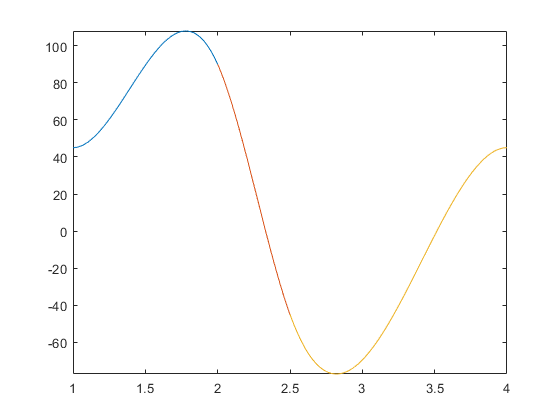

%Graphic the spline curve
figure
fplot(spa,[1,2])
hold on
fplot(spb,[2 2.5])
fplot(spc,[2.5 4])

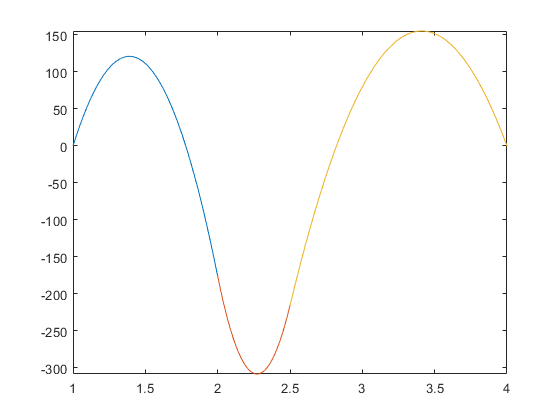


figure
fplot(diff(spa,t),[1,2])
hold on
fplot(diff(spb,t),[2 2.5])
fplot(diff(spc,t),[2.5 4])

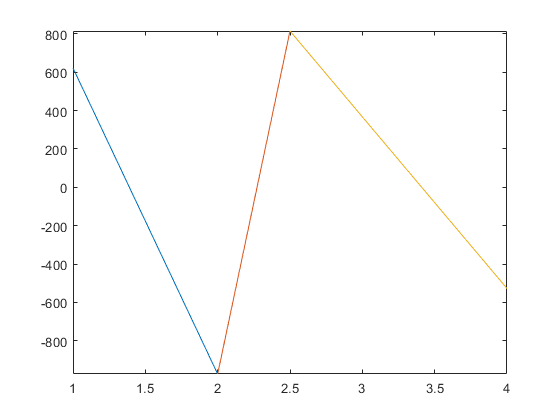


figure
fplot(diff(diff(spa,t),t),[1,2])
hold on
fplot(diff(diff(spb,t),t),[2 2.5])
fplot(diff(diff(spc,t),t),[2.5 4])